# **Chapter 6: Linear Model Selection and Regularization**

## **6.5 Lab 1: Subset Selection Methods**

### **6.5.1 Best Subset Selection**

[**Introduction to Feature Selection**](https://www.mathworks.com/help/stats/feature-selection.html)

clear all; clc; close all;
Hitters = readtable("Data\Hitters.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Hitters.League = categorical(Hitters.League);
Hitters.Division = categorical(Hitters.Division);
Hitters.NewLeague = categorical(Hitters.NewLeague);

Hitters.Properties.VariableNames

ans = 1×20 cell array
    {'AtBat'}    {'Hits'}    {'HmRun'}    {'Runs'}    {'RBI'}    {'Walks'}    {'Years'}    {'CAtBat'}    {'CHits'}    {'CHmRun'}    {'CRuns'}    {'CRBI'}    {'CWalks'}    {'League'}    {'Division'}    {'PutOuts'}    {'Assists'}    {'Errors'}    {'Salary'}    {'NewLeague'}


size(Hitters)

ans =    322    20


sum(isnan(Hitters.Salary))

ans = 59

Hitters = rmmissing(Hitters,1);
size(Hitters)

ans =    263    20


sum(isnan(Hitters.Salary))

ans = 0

The [sequentialfs](https://www.mathworks.com/help/stats/sequentialfs.html) input is a continuous variable. If table A contains categorical variables, we use **dummytable** functions (local functions) to encode them into continuous variables.

HittersDummy = dummytable(Hitters);
XTable = removevars(HittersDummy,"Salary");
yTable = HittersDummy(:,"Salary");
opts = statset('Display','iter');

CritSSE = @(X,y)fitlm(X,y).SSE;
[inmodel,history] = sequentialfs(CritSSE,XTable{:,:},yTable{:,:},...
    'nullmodel',true,"nfeatures",19, 'direction','forward','cv','none');

Summary of the presence of features in the model (0 - absent, 1 - present) 

array2table(history.In,'VariableNames',XTable.Properties.VariableNames)

ans = 20×22 table
    AtBat    Hits     HmRun    Runs      RBI     Walks    Years    CAtBat    CHits    CHmRun    CRuns    CRBI     CWalks    League_A    League_N    Division_E    Division_W    PutOuts    Assists    Errors    NewLeague_A    NewLeague_N
    _____    _____    _____    _____    _____    _____    _____    ______    _____    ______    _____    _____    ______    ________   

As expected, the Sum of squared errors decreases monotonically as more variables are included

history.Crit

ans = 	1.0e+07 *

    5.3319    3.6180    3.0647    2.9249    2.7971    2.7150    2.6195    2.5954    2.5159    2.4814    2.4500    2.4387    2.4333    2.4289    2.4249    2.4235    2.4219    2.4209    2.4202    2.4201


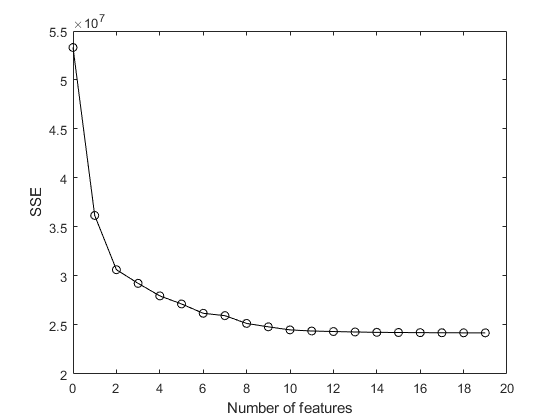

plot(sum(history.In.'),history.Crit,'Marker','o','Color','k');
xlabel('Number of features'); ylabel('SSE');

Fit model Best Subset Selection with 7 features

regfitFull = fitlm([XTable, yTable],'ResponseVar','Salary',...
    'PredictorVars',logical([history.In(7,:),0]));

### 6.5.2 Forward and Backward Stepwise Selection

`Forward `selections 

regfitFwd = stepwiselm(Hitters,'constant','ResponseVar','Salary',...
    'Upper','linear','Criterion','sse')

1. Adding CRBI, FStat = 123.6438, pValue = 9.070948e-24
2. Adding Hits, FStat = 46.942, pValue = 5.27536e-11
3. Adding PutOuts, FStat = 12.3726, pValue = 0.000514329
4. Adding Division, FStat = 11.7922, pValue = 0.000692808
5. Adding AtBat, FStat = 7.7711, pValue = 0.0057053
6. Adding Walks, FStat = 9.3331, pValue = 0.0024884


regfitFwd = Linear regression model:
    Salary ~ 1 + AtBat + Hits + Walks + CRBI + Division + PutOuts

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     91.512           65     1.4079       0.16038
    AtBat          -1.8686      0.52742    -3.5429    0.00047024
    Hits            7.6044       1.6625      4.574    7.4616e-06
    Walks           3.6976       1.2104      3.055     0.0024884
    CRBI           0.64302     0.064434     9.9794     5.045e-20
    Division_W     -122.95        39.82    -3.0877     0.0022394
    PutOuts        0.26431     0.074772     3.5349    0.00048406


Number of observations: 263, 

`Backward `selections 

regfitBwd = stepwiselm(Hitters,'linear','ResponseVar','Salary',...
    'Upper','constant','Criterion','sse')

1. Removing CHmRun, FStat = 0.011425, pValue = 0.91497
2. Removing Years, FStat = 0.076717, pValue = 0.78203
3. Removing NewLeague, FStat = 0.1005, pValue = 0.7515
4. Removing RBI, FStat = 0.16048, pValue = 0.68906
5. Removing CHits, FStat = 0.13742, pValue = 0.71118
6. Removing HmRun, FStat = 0.41408, pValue = 0.5205
7. Removing Errors, FStat = 0.45193, pValue = 0.50204
8. Removing Runs, FStat = 0.55595, pValue = 0.4566
9. Removing League, FStat = 1.1636, pValue = 0.28176


regfitBwd = Linear regression model:
    Salary ~ 1 + AtBat + Hits + Walks + CAtBat + CRuns + CRBI + CWalks + Division + PutOuts + Assists

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      162.54      66.908     2.4292       0.01583
    AtBat           -2.1687      0.5363    -4.0437    6.9962e-05
    Hits              6.918      1.6466     4.2013    3.6865e-05
    Walks            5.7732      1.5848     3.6428    0.00032736
    CAtBat         -0.13008    0.055496    -2.3439      0.019858
    CRuns            1.4082      0.3904     3.6072    0.00037312
    CRBI            0.77431     0.20961     3.6941     0.000

% Best Subset Selection
regfitFull.Coefficients(:,1)

ans = 7×1 table
                   Estimate
                   ________

    (Intercept)     -31.44 
    AtBat          -1.8686 
    Hits            7.6044 
    Walks           3.6976 
    CRBI           0.64302 
    Division_E      122.95 
    PutOuts        0.26431 


% Forward selections 
regfitFwd.Coefficients(:,1)

ans = 7×1 table
                   Estimate
                   ________

    (Intercept)     91.512 
    AtBat          -1.8686 
    Hits            7.6044 
    Walks           3.6976 
    CRBI           0.64302 
    Division_W     -122.95 
    PutOuts        0.26431 


% Backward selections 
regfitBwd.Coefficients(:,1)

ans = 11×1 table
                   Estimate
                   ________

    (Intercept)      162.54
    AtBat           -2.1687
    Hits              6.918
    Walks            5.7732
    CAtBat         -0.13008
    CRuns            1.4082
    CRBI            0.77431
    CWalks         -0.83083
    Division_W      -112.38
    PutOuts         0.29737
    Assists         0.28317


### 6.5.3 Choosing Among Models Using the Validation Set Approach and Cross-Validation

rng default;
train = randsample([true, false],size(Hitters,1),true).';
test = ~train;

[~,history] = sequentialfs(CritSSE,XTable{train,:},yTable{train,:},...
    'nullmodel',true,"nfeatures",19, 'direction','forward','cv','none');

for i = 1:length(history.Crit)
    lmFit = fitlm([XTable(train,:), yTable(train,:)],'ResponseVar','Salary',...
    'PredictorVars',logical([history.In(i,:),0]));
    pred = predict(lmFit,XTable(test,:));
    valError(i) = mean((yTable{test,:} - pred).^2);
end

valError

valError = 	1.0e+05 *

    2.0939    1.5997    1.4389    1.5173    1.6723    1.6165    1.5371    1.5023    1.5440    1.5025    1.5117    1.5280    1.5197    1.5205    1.5574    1.5714    1.5794    1.5828    1.5819    1.5854


find(valError == min(valError))

ans = 3

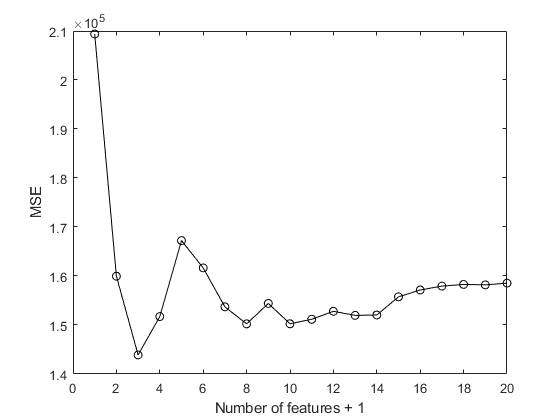

plot(valError,'Marker','o','Color','k');
xlabel('Number of features + 1'); ylabel('MSE');

fitlm([XTable(train,:), yTable(train,:)],'ResponseVar','Salary',...
    'PredictorVars',logical([history.In(3,:),0])).Coefficients(:,1)

ans = 3×1 table
                   Estimate
                   ________

    (Intercept)    -116.35 
    Hits            3.6094 
    CRBI           0.75857 


cv = cvpartition(size(Hitters,1),'KFold',10);
for kFold = 1:10
    for i = 1:length(history.Crit)
        lmFit = fitlm([XTable(cv.training(kFold),:), yTable(cv.training(kFold),:)],'ResponseVar','Salary',...
        'PredictorVars',logical([history.In(i,:),0]));
        pred = predict(lmFit,XTable(cv.test(kFold),:));
        valErrorFold(kFold,i) = mean((yTable{cv.test(kFold),:} - pred).^2);
    end
end

meanCvErrors = mean(valErrorFold);
meanCvErrors

meanCvErrors = 	1.0e+05 *

    2.0340    1.4537    1.2508    1.2118    1.2318    1.1943    1.1509    1.1351    1.1484    1.1130    1.1304    1.1375    1.1375    1.1453    1.1234    1.1474    1.1651    1.1819    1.1981    1.2144


find(meanCvErrors == min(meanCvErrors))

ans = 10

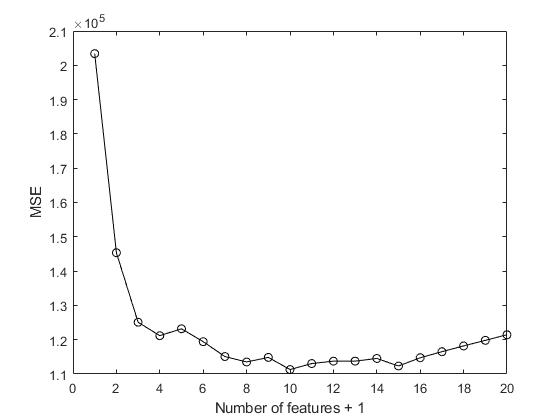

plot(meanCvErrors,'Marker','o','Color','k');
xlabel('Number of features + 1'); ylabel('MSE');

fitlm([XTable(train,:), yTable(train,:)],'ResponseVar','Salary',...
    'PredictorVars',logical([history.In(15,:),0])).Coefficients(:,1)

ans = 15×1 table
                   Estimate
                   ________

    (Intercept)      80.711
    AtBat          -0.94207
    Hits             3.5639
    Walks            5.7853
    CAtBat         -0.40158
    CHits            1.4259
    CRuns          -0.27451
    CRBI             1.3877
    CWalks         -0.58037
    League_A        -113.47
    Division_E       108.33
    PutOuts         0.38403
    Assists         0.22379
    Errors          -4.6245
    NewLeague_N     -142.87


## 6.6 Lab 2: Ridge Regression and the Lasso

### 6.6.1 Ridge Regression

grid = 10.^(10:-12/99:-2).'; % гипепараметр
ridgeMod = ridge(yTable{:,:},XTable{:,:},grid,0); 

size(ridgeMod)

ans =     23   100


grid(50)

ans = 1.1498e+04

Table of coefficients when λ = 11,498

array2table(ridgeMod(:,50).','VariableNames',["(Intercept)", XTable.Properties.VariableNames])

ans = 1×23 table
    (Intercept)     AtBat        Hits       HmRun      Runs        RBI       Walks      Years      CAtBat        CHits       CHmRun      CRuns       CRBI       CWalks     League_A    League_N     Division_E    Division_W    PutOuts      Assists      Errors      NewLeague_A    NewLeague_N
    ___________    ________    ________    _______    _______    _______    _______    _______    _________    _________    _

Calculate $l_2$ norm

sqrt(sum(ridgeMod(2:end,50).^2))

ans = 5.2501

grid(60)

ans = 705.4802

array2table(ridgeMod(:,60).','VariableNames',["(Intercept)", XTable.Properties.VariableNames])

ans = 1×23 table
    (Intercept)     AtBat      Hits      HmRun      Runs        RBI      Walks     Years     CAtBat       CHits      CHmRun      CRuns       CRBI       CWalks     League_A    League_N    Division_E    Division_W    PutOuts     Assists      Errors     NewLeague_A    NewLeague_N
    ___________    _______    _______    ______    _______    _______    ______    _____    _________    ________    _______   

sqrt(sum(ridgeMod(2:end,60).^2))

ans = 44.9962

We can obtain the ridge regression coefficients for a new value $\lambda =50$

predict = ridge(yTable{:,:},XTable{:,:},50,0);
array2table(predict','VariableNames',["(Intercept)", XTable.Properties.VariableNames])

ans = 1×23 table
    (Intercept)     AtBat       Hits      HmRun       Runs       RBI      Walks      Years      CAtBat       CHits      CHmRun      CRuns      CRBI       CWalks      League_A    League_N    Division_E    Division_W    PutOuts    Assists     Errors     NewLeague_A    NewLeague_N
    ___________    ________    ______    ________    ______    _______    ______    _______    _________    ________    _______

Set a random seed so that the results obtained will be reproducible.

rng default;
cv = cvpartition(size(Hitters,1),'HoldOut',0.5);
train = cv.training;
test = cv.test;

Fit a ridge regression model on the training set, and evaluate its MSE on the test set, using $\lambda =4$

ridgeMod = ridge(yTable{train,:},XTable{train,:},4,0); 

Get predictions for a test set

ridgePred = ridgeMod(1) + XTable{test,:}*ridgeMod(2:end);

Compute MSE

mean((ridgePred - yTable{test,:}).^2)

ans = 1.1849e+05

Compute the test set MSE if we had instead simply fit a model with just an intercept

mean((mean(yTable{train,:}) - yTable{test,:}).^2)

ans = 1.7049e+05

Fit a ridge regression model on the training set, and evaluate its MSE on the test set, using $\lambda ={10}^{10}$

ridgeMod = ridge(yTable{train,:},XTable{train,:},10^10,0); 
ridgePred = ridgeMod(1) + XTable{test,:}*ridgeMod(2:end);
mean((ridgePred - yTable{test,:}).^2)

ans = 1.7049e+05

Compare the regression coefficients obtained by the least squares method (OLS) and the ridge regression model with $\lambda =0$

ridgeMod = ridge(yTable{train,:},XTable{train,:},0,0); 

ridgePred = ridgeMod(1) + XTable{test,:}*ridgeMod(2:end);
mean((ridgePred - yTable{test,:}).^2)

ans = 1.3181e+05

The regression coefficients obtained in the ridge regression model

array2table(ridgeMod,'RowNames',["(Intercept)", XTable.Properties.VariableNames])

ans = 23×1 table
                   ridgeMod
                   ________

    (Intercept)      137.64
    AtBat           -1.5452
    Hits             4.2289
    HmRun            6.1185
    Runs            -1.5366
    RBI               2.086
    Walks            2.5713
    Years           -1.8759
    CAtBat          -0.5523
    CHits            1.6115
    CHmRun          -1.2941
    CRuns            1.3608
    CRBI            0.76836
    CWalks         -0.39841
    League_A        -30.697
    League_N              0


The regression coefficients obtained by the least squares method (OLS)

fitlm(XTable{train,:}, yTable{train,:},'PredictorVars',...
    XTable.Properties.VariableNames).Coefficients(:,1)

ans = 23×1 table
                   Estimate
                   ________

    (Intercept)           0
    AtBat           -1.5452
    Hits             4.2289
    HmRun            6.1185
    Runs            -1.5366
    RBI               2.086
    Walks            2.5713
    Years           -1.8759
    CAtBat          -0.5523
    CHits            1.6115
    CHmRun          -1.2941
    CRuns            1.3608
    CRBI            0.76836
    CWalks         -0.39841
    League_A              0
    League_N         30.697


**Comment**: When $\lambda =0$, the coefficients (except intercept $\beta_0$) of the ridge regression model are equal to the coefficients obtained from the OLS method. In other words, when $\lambda =0$, the ridge regression method becomes the OLS method.

Method 1:

rng default;
cv = cvpartition(size(Hitters,1),'KFold',10);
for kFold = 1:10
    ridgeMod = ridge(yTable{cv.training(kFold),:},XTable{cv.training(kFold),:},grid,0); 
    ridgePred = ridgeMod(1,:) + XTable{cv.test(kFold),:}*ridgeMod(2:end,:);
    % Compute MSE
    ridgeMSEkFold(kFold,:) = mean((ridgePred - yTable{cv.test(kFold),:}).^2);
end
ridgeMSE = mean(ridgeMSEkFold);

Plot graph of MSE's dependence on lamda

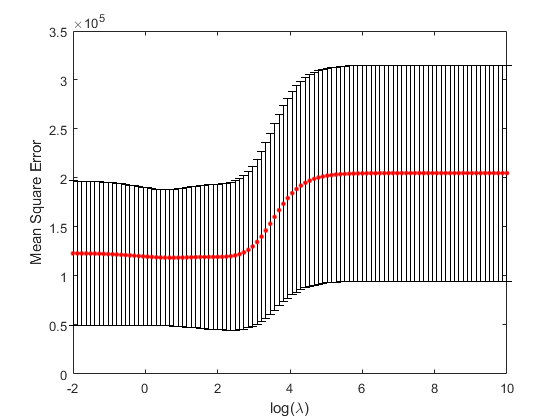

errorbar(log10(grid),ridgeMSE,std(ridgeMSEkFold),'.','MarkerSize',10,...
    'MarkerEdgeColor','red','Color','k');
xlabel('log(\lambda)'); ylabel('Mean Square Error');

Compute the value of $\lambda$, at which MSE reaches minimum

bestlam = grid(ridgeMSE == min(ridgeMSE))

bestlam = 6.1359

Compute MSE with $\lambda =\textrm{bestlam}$

ridgeMod = ridge(yTable{train,:},XTable{train,:},bestlam,0); 
ridgePred = ridgeMod(1) + XTable{test,:}*ridgeMod(2:end);
mean((ridgePred - yTable{test,:}).^2)

ans = 1.1724e+05

Refit our ridge regression model on the full data set, using the value of λ chosen by cross-validation, and examine the coefficient estimates.

ridgeMod = ridge(yTable{:,:},XTable{:,:},bestlam,0); 

The regression coefficients obtained in the ridge regression model

array2table(ridgeMod,'RowNames',["(Intercept)", XTable.Properties.VariableNames])

ans = 23×1 table
                   ridgeMod 
                   _________

    (Intercept)       75.648
    AtBat            -1.1769
    Hits              4.1943
    HmRun           -0.59553
    Runs             0.49145
    RBI              0.42591
    Walks             4.3605
    Years             -10.89
    CAtBat         -0.021125
    CHits            0.17012
    CHmRun           0.72459
    CRuns            0.45964
    CRBI             0.31708
    CWalks          -0.45487
    League_A         -31.196
    League_N          31.196


Method 2: using **Lasso Plot with Cross-Validated Fits**

rng default

`Alpha` close to `0` approaches [ridge regression](https://localhost:31515/static/help/stats/ridge-regression.html)

[cvOut,FitInfo] = lasso(XTable{train,:},yTable{train,:},...
    "Alpha",10^-20,"Lambda",grid,"CV",10);

Examine the cross-validation plot to see the effect of the `Lambda` regularization parameter.

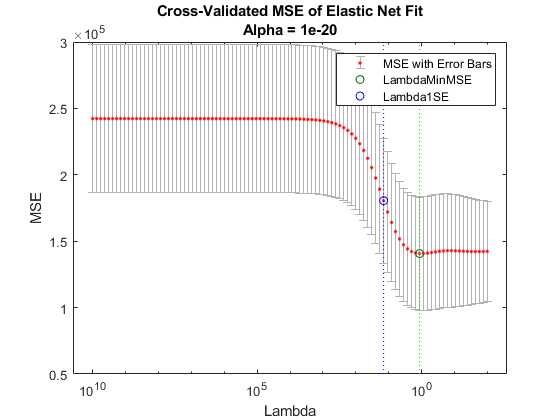

lassoPlot(cvOut,FitInfo,'PlotType','CV',"XScale","log");
legend('show') % Show legend

Compute the value of $\lambda$, at which MSE reaches minimum

bestlam2 = FitInfo.LambdaMinMSE

bestlam2 = 1.1498

Minimum MSE

FitInfo.MSE(FitInfo.IndexMinMSE)

ans = 1.4069e+05

[Predict Values Using Lasso Regularization](https://www.mathworks.com/help/releases/R2019b/stats/lassoglm.html#d117e523009)

IndexMinMSE = FitInfo.IndexMinMSE;
% lassoPred = glmval([FitInfo.Intercept(IndexMinMSE);cvOut(:,IndexMinMSE)],XTable{test,:});
lassoPred = FitInfo.Intercept(IndexMinMSE) + XTable{test,:}*cvOut(:,IndexMinMSE);
mean((lassoPred - yTable{test,:}).^2)

ans = 1.0771e+05

### 6.6.2 The Lasso

"Alpha" = 1 (defaul | l[asso regression](https://www.mathworks.com/help/stats/lasso.html)) or 0 ([ridge regression](https://www.mathworks.com/help/stats/ridge-regression.html))

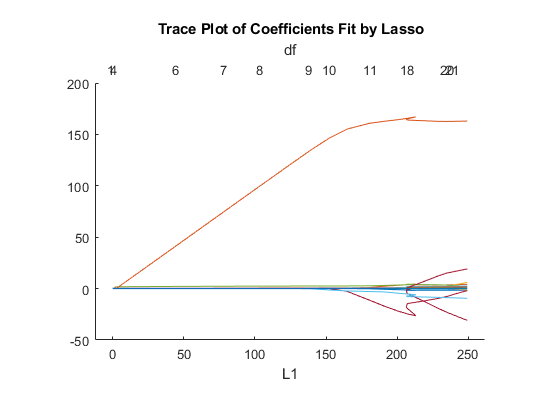

lassoMod = lasso(XTable{train,:},yTable{train,:},"Alpha",1,"Lambda",grid);
lassoPlot(lassoMod);

**Lasso Plot with Cross-Validated Fits**

rng default
[cvOut,FitInfo] = lasso(XTable{train,:},yTable{train,:},...
    "Lambda",grid,"CV",10);

Examine the cross-validation plot to see the effect of the `Lambda` regularization parameter.

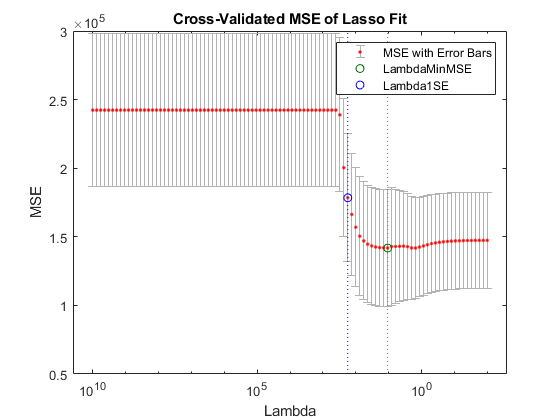

lassoPlot(cvOut,FitInfo,'PlotType','CV',"XScale","log");
legend('show') % Show legend

Compute the value of $\lambda$, at which MSE reaches minimum

bestlam = FitInfo.LambdaMinMSE

bestlam = 10.7227

Minimum MSE

FitInfo.MSE(FitInfo.IndexMinMSE)

ans = 1.4184e+05

[Predict Values Using Lasso Regularization](https://www.mathworks.com/help/releases/R2019b/stats/lassoglm.html#d117e523009)

IndexMinMSE = FitInfo.IndexMinMSE;
% lassoPred = glmval([FitInfo.Intercept(IndexMinMSE);cvOut(:,IndexMinMSE)],XTable{test,:});
lassoPred = FitInfo.Intercept(IndexMinMSE) + XTable{test,:}*cvOut(:,IndexMinMSE);
mean((lassoPred - yTable{test,:}).^2)

ans = 1.2385e+05

[out,FitInfo] = lasso(XTable{:,:},yTable{:,:},...
    "Alpha",1,"Lambda",bestlam);

The regression coefficients obtained by the Lasso method with $\lambda =\textrm{bestlam}$

lassoCoef = array2table([FitInfo.Intercept; out]','VariableNames',["(Intercept)", XTable.Properties.VariableNames])

lassoCoef = 1×23 table
    (Intercept)    AtBat     Hits     HmRun    Runs    RBI    Walks     Years    CAtBat    CHits     CHmRun      CRuns      CRBI     CWalks    League_A     League_N     Division_E    Division_W    PutOuts    Assists     Errors     NewLeague_A    NewLeague_N
    ___________    _____    ______    _____    ____    ___    ______    _____    ______    _____    ________    _______    <

removevars(lassoCoef,find(lassoCoef{:,:} == 0))

ans = 1×11 table
    (Intercept)     Hits     Walks      CHmRun      CRuns      CRBI     League_A     League_N     Division_E    PutOuts     Errors 
    ___________    ______    ______    ________    _______    ______    ________    __________    __________    _______    ________

      -96.68       1.9898    2.2591    0.019695    0.21281    0.4153     -16.74     1.3565e-11      114.08      0.2341     -0.63484


## 6.7 Lab 3: PCR and PLS Regression

### 6.7.1 Principal Components Regression

XTablePCA = removevars(XTable,{'Division_W','League_N','NewLeague_N'});

[Choosing the Number of Components with Cross-Validation](https://www.mathworks.com/help/stats/examples/partial-least-squares-regression-and-principal-components-regression.html#d120e5056)

For PCR, `crossval` combined with a simple function to compute the sum of squared errors for PCR, can estimate the MSEP, again using 10-fold cross-validation.

PCRmsep = sum(crossval(@pcrsse1,XTablePCA{train,:},yTable{train,:},'KFold',10),1) / size(XTablePCA{train,:},1);

The MSEP curve for PLSR indicates that two or three components does about as good a job as possible. On the other hand, PCR needs four components to get the same prediction accuracy.

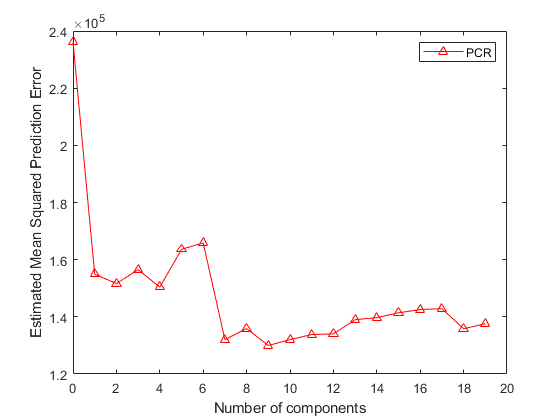

figure
plot(0:19,PCRmsep,'r-^');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend({'PCR'},'location','NE');

find(PCRmsep == min(PCRmsep)) - 1

ans = 9

[We now perform PCR on the training data and evaluate its test set performance](https://www.mathworks.com/help/stats/examples/partial-least-squares-regression-and-principal-components-regression.html#d120e4947)

[PCALoadings,PCAScores,PCAVar] = pca(XTablePCA{train,:},'Economy',false);
betaPCR = regress(yTable{train,:}-mean(yTable{train,:}), PCAScores(:,1:9));
betaPCR = PCALoadings(:,1:9)*betaPCR;
betaPCR = [mean(yTable{train,:}) - mean(XTablePCA{train,:})*betaPCR; betaPCR];

Now we find that the lowest cross-validation error occurs when M = 9 component are used. 

yfitPCR = [ones(size(XTablePCA{test,:},1),1) XTablePCA{test,:}]*betaPCR;

We compute the test MSE as follows

mean((yfitPCR - yTable{test,:}).^2)

ans = 1.3572e+05

### 6.7.2 Partial Least Squares

Cross validation with Partial Least Squares

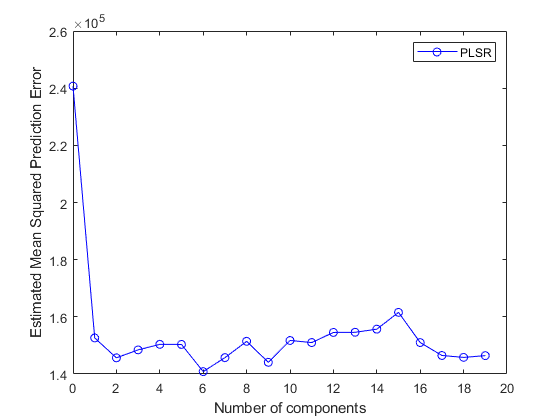

rng default;
[~,~,~,~,~,~,PLSmsep] = plsregress(XTablePCA{train,:},yTable{train,:},19,'CV',10);
figure
plot(0:19,PLSmsep(2,:),'b-o');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend({'PLSR'},'location','NE');

find(PLSmsep(2,:) == min(PLSmsep(2,:))) - 1

ans = 6

The lowest cross-validation error occurs when only M = 6 partial least squares directions are used.

[~,~,~,~,betaPLS] = plsregress(XTablePCA{test,:},yTable{test,:},6);
yfitPLS = [ones(size(XTablePCA{test,:},1),1) XTablePCA{test,:}]*betaPLS;

 We now evaluate the corresponding test set MSE

mean((yfitPLS - yTable{test,:}).^2)

ans = 8.9331e+04

Finally, we perform PLS using the full data set, using M = 6, the number of components identified by cross-validation

[~,~,~,~,~,PCTVAR] = plsregress(XTablePCA{:,:},yTable{:,:},6);
cumsum(PCTVAR(2,:))*100

ans =    28.4458   40.5295   45.7120   47.1360   48.4645   48.8100
